# Signal Processing with MATLAB

## Lesson 1: Generate a Signal

### TASK 1:

First, you need to choose the sample times where the signal should get generated. You can choose sample times by specifying the:

Sample rate fs

Start time

End time

You can create time steps from a to b with the colon operator:

a:1/fs:b

The distance between two samples is 1 over the sample rate.

TASK

Specify a sample rate of 100 Hz in a variable named fs.

Then create a signal named t that extends from  0 to 3, with time steps that are 1/fs.

fs=100

fs = 100

t=0:1/fs:3

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


### TASK 2:

A straightforward way to make a sine wave is using the sin function:

s = sin(2*pi*f*t)

where f is the frequency, and t are the time steps.

TASK

Create a sine signal named sig at the sample times in t. Use a frequency of 5 Hz.

Then create a plot of sig versus t.

sig=sin(2*pi*5*t)

sig =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


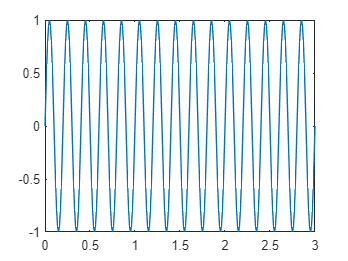

plot(t,sig)

### TASK 3:

To create a signal with multiple tones, you can add sine waves together.

TASK

Create another signal with a tone at 3 Hz. Add it to the 5 Hz tone from the previous task and name the result sig. Then create a plot of sig versus t.

sig=sig+sin(2*pi*3*t)

sig =          0    0.4964    0.9559    1.3448    1.6356    1.8090    1.8559    1.7776    1.5858    1.3011    0.9511    0.5673    0.1827   -0.1716   -0.4693   -0.6910   -0.8257   -0.8718   -0.8365   -0.7348   -0.5878   -0.4200   -0.2565   -0.1208   -0.0312         0   -0.0312   -0.1208   -0.2565   -0.4200   -0.5878   -0.7348   -0.8365   -0.8718   -0.8257   -0.6910   -0.4693   -0.1716    0.1827    0.5673    0.9511    1.3011    1.5858    1.7776    1.8559    1.8090    1.6356    1.3448    0.9559    0.4964


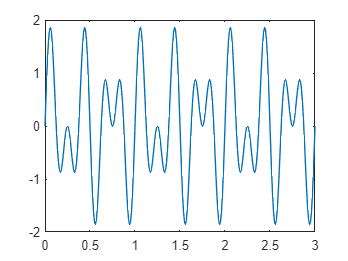

plot(t,sig)

### Further Practice:

Try using the pspectrum function to view the spectrum of sig:

pspectrum(sig,fs)

Remember that you can execute your script by clicking the Run or Run Section button in the MATLAB Toolstrip.

When you're finished practicing, you may move on to the next section.

pspectrum(sig,fs)

'pspectrum' requires Signal Processing Toolbox.